% This program will take in input of your caffeine intake and determine
% whether it is safe or not to take any other medication/drugs

%prompts for inputs
prompt1 = "Please enter an estimate in mg of your caffeine intake: ";
prompt2 = "Please enter your body weight in kg (if using lbs, divide value by 2.205 and enter your result): ";
prompt3 = "Please enter an estimate in minutes since ingestion: ";

%declaring main variables and gathering input
cafIntake = input(prompt1);
bodyWeight = input(prompt2);
elapsedTime = input(prompt3);
if elapsedTime == 0
    elapsedTime = 1;
end

%performing calculations
[safe_limit, max_limit] = caf_limit(bodyWeight);
[percent_safe, percent_max] = caf_percent(cafIntake, safe_limit, max_limit);

% displaying initial statistics

fprintf("You have consumed %d mg of caffeine, which is %0.2f%% of your daily safe limit.", cafIntake, percent_safe)

You have consumed 200 mg of caffeine, which is 69.99% of your daily safe limit.

fprintf("This is %0.2f%% of your daily max limit.", percent_max)

This is 34.99% of your daily max limit.

fprintf("Your estimated daily safe limit of caffeine is %0.2f mg, and your estimated daily maximum limit of caffeine is %0.2f mg.", safe_limit, max_limit)

Your estimated daily safe limit of caffeine is 285.76 mg, and your estimated daily maximum limit of caffeine is 571.53 mg.


% displaying individualized message based on intake
if cafIntake <= safe_limit
    fprintf("You are within your safe limits, and should not experience any negative symptoms.")
elseif cafIntake > safe_limit && cafIntake <= max_limit
    fprintf("You have exceeded your safe limits! While you are within your max limits, you may experience some negative symptoms")
else
    fprintf("YOU HAVE EXCEEDED YOUR MAX LIMITS!!! IT IS HIGHLY LIKELY YOU WILL EXPERIENCE NEGATIVE SYMPTOMS!!!")
end

You are within your safe limits, and should not experience any negative symptoms.


%print a warning for health implications
fprintf("According to the FDA, the average American is suggested to keep their caffeine intake below 400 mg.")

According to the FDA, the average American is suggested to keep their caffeine intake below 400 mg.

fprintf ("Please consult a doctor if you experience negative symptoms, such as insomnia, anxiety, chest pain, headaches, or irregular heartbeat.")

Please consult a doctor if you experience negative symptoms, such as insomnia, anxiety, chest pain, headaches, or irregular heartbeat.


% caffeine is absorbed into bloodstream typically at 45 minutes, and a typical half life of 5.7 hours (or 342 minutes)

%determining how long it will take to reach neglible* caffeine levels
%see function definition for clarification on "negligble"
endTime = cafLevel30(cafIntake);
[endTimeHours, num_Halflives] = caf_finalStats(endTime)

endTimeHours = 15.6167

num_Halflives = 2.7398

[minLeft, hoursLeft, half_livesLeft] = timeLeft(elapsedTime, endTime)

minLeft = 936

hoursLeft = 15.6000

half_livesLeft = 2.7368

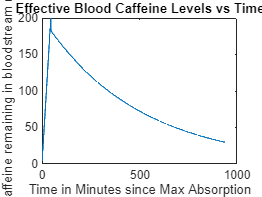


%recording caffine blood concentration data for every minute from max levels in bloodstream to neglible
%levels in bloodstream.
for i = elapsedTime:endTime
    if i <= 45
        caf_remains(i) = caf_abs45(cafIntake,i);
    else
        caf_remains(i) = caf_reduction(cafIntake, i);
    end
end

%graphing caffeine metabolism
figure;
plot(caf_remains)
title("Effective Blood Caffeine Levels vs Time")
xlabel("Time in Minutes since Max Absorption")
ylabel("Caffeine remaining in bloodstream (mg)")


% printing out final results on caffeine metabolism 
fprintf("It will take approximately %i minutes, or approximately %0.2f hours to reduce caffeine levels to neglible effects. ", endTime, endTimeHours)

It will take approximately 937 minutes, or approximately 15.62 hours to reduce caffeine levels to neglible effects. 

fprintf("This will take approximately %0.2f half-lives.", num_Halflives)

This will take approximately 2.74 half-lives.

fprintf("It has been %i minutes since you ingested caffeine.", elapsedTime)

It has been 1 minutes since you ingested caffeine.

fprintf("It will take %i more minutes until it is safe to consume other medications", minLeft)

It will take 936 more minutes until it is safe to consume other medications

fprintf("This is approximately %0.2f hours, or %0.2f half lives.", hoursLeft, half_livesLeft)

This is approximately 15.60 hours, or 2.74 half lives.




%function definitions

function [safe_limit, max_limit] = caf_limit(bodyWeight)
%this function determinnes safe and max limits of caffeine based on
%bodyweight.
    safe_limit = bodyWeight * 3;
    max_limit = bodyWeight * 6;
end

function [percent_safe, percent_max] = caf_percent(cafIntake, safe_limit, max_limit)
%this function uses your caffeine intake and compares it to your safe/max
%levels.
    percent_safe = (cafIntake / safe_limit) * 100;
    percent_max  = (cafIntake / max_limit) * 100;
end

function caf_effectTime = cafLevel30(cafIntake)
%this function uses your caffeine intake and determines how long it would
%take to reduce it to a level where there aren't noticeable effects
%(*research has determined this to be around 30 mg where caffeine is
%considered neglible in the body).
    caf_effectTime = round(342 * (log(30 / cafIntake) / log(0.5))) + 1;
end

function caf_abs = caf_abs45(cafIntake, time)
%this function takes in your caffeine intake and the current elapsed time
%and returns the caffeine level in your body after ingestion. This is a
%steady, linear increase
    caf_abs = time * (cafIntake / 45);
end

function caf_remains = caf_reduction(cafIntake, time)
%this function takes your caffeine intake and the current elapsed time and
%returns the caffeine level in your body after depletion begins. This is a
%exponential decay
    k = (5.7 * 60) / log(2);
    caf_remains = cafIntake * exp((-1 * time) / k);
end

function [endTimeHours, num_Halflives] = caf_finalStats(endTime)
%this function uses the calculated end time and converts it from minutes to
%hours and number of half lives (was created just to avoid having
%calculations in main body of program
    endTimeHours = endTime / 60;
    num_Halflives = endTimeHours / 5.7;
end

function [minLeft, hoursLeft, half_livesLeft] = timeLeft(elapsedTime, endTime)
% this function is used just to perform the calculation fo finding out how
% much time you have left
    minLeft = endTime - elapsedTime;
    hoursLeft = minLeft / 60;
    half_livesLeft = hoursLeft / 5.7;
end
